# validation with L8

clc 
clear
close all

## Loading the k-scale Factor

load('Egypt1Gain.mat')


## Loading the Landsat 8 data over Egypt 1

load('L8Egypt1-OPT7822018156.mat')


## selecting the bands for analysis

% Bands required For analysis
bandSel = [2,3,4,5,6,7,8];

% filtering the landSat 8 data 
[nanRow, ~] =  (find(isnan(Input)));

% filtering the landsat that have view zenith angle more than 6 and solar zenith angle more than 49
[viewZenithfil,~] =  find(abs(Input(:,13)) > 23);
[solarZenithfil,~] = find(Input(:,11) < 13 & Input(:,11) > 59);

dataRemove = [nanRow;viewZenithfil;solarZenithfil];

% removing the data 
Input(dataRemove,:)= [];


## Sorting the Data



% taking the transpose of the refData which contains the informatio
refData = Input;

% Bands reflectance selection of the Hyperion
reflectance = refData(:,bandSel);

% Solar zenith angle form the Ref data
sza_angle = refData(:,11);

% view zeniht angl from the Ref Data
vza_angle = refData(:,13);

% squared View Zenith angle
sq_vza_angle = (vza_angle) .* vza_angle;

decimalYear = refData(:,15);


## Filtering the Data


% outliersIndex = [];
% for band =  1:6
%     % deleteOutliers uses Grubbs test to identify the outliers in the data
%     [~,indexNumber,outlier] = deleteoutliers(reflectance(:,band),0.05);
%     outliersIndex = [outliersIndex;indexNumber];
% end
outliersIndex = median_absolute_deviation(reflectance,6,2);
reflectance(outliersIndex,:) = [];
sza_angle(outliersIndex,:) = [];
vza_angle(outliersIndex,:) = [];
sq_vza_angle(outliersIndex,:) = [];
decimalYear(outliersIndex,:) = [];

## Plotting the data

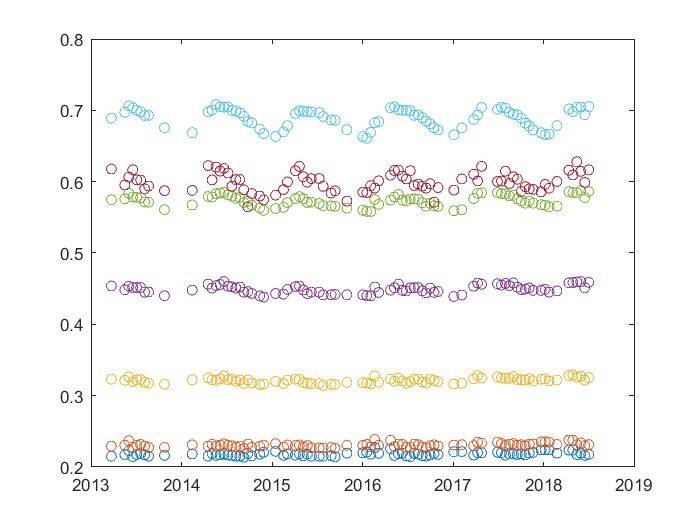

figure
for band  = 1:length(bandSel)
   plot(decimalYear,reflectance(:,band),'LineStyle','None','Marker','o')
   hold on
end

## Calculating the uncertainty of Egypt 1

egyptL8Mean = mean(reflectance);
egyptL8Std = std(reflectance);
egyptL8Uncertainty = (egyptL8Std ./ egyptL8Mean)*100;
save('egyptL8Uncertainty.mat','egyptL8Uncertainty')


## Satellite Number in the bander function

% satellite number in bander function 
satelliteNumber =  24;


## Coefficient for Egypt 1 (MODIS)

load('modis_solar_zenith_info.mat')
modisCoeff = coeffvalues(coeff.slope)

modisCoeff =    -0.0008    0.0002    0.0047   -0.0038


sza  = dataset({modisCoeff,'a','b','c','d'});


## Coefficienf for Egypt 1 (Hyperion)

load('hyperion_view_zenith_info.mat')
vza.lin  =coeffvalues(coeffHy.linear)

vza = struct with fields:
    lin: [9.4667e-10 -2.7075e-06 3.2871e-04]


vza.lin = dataset({vza.lin,'a','b','c'});

vza.qua = coeffvalues(coeffHy.quadratic)

vza = struct with fields:
    lin: [1×3 dataset]
    qua: [-2.1067e-11 8.8809e-08 2.3968e-05]


vza.qua = dataset({vza.qua,'a','b','c'});



## Plotting the averaged hyperion

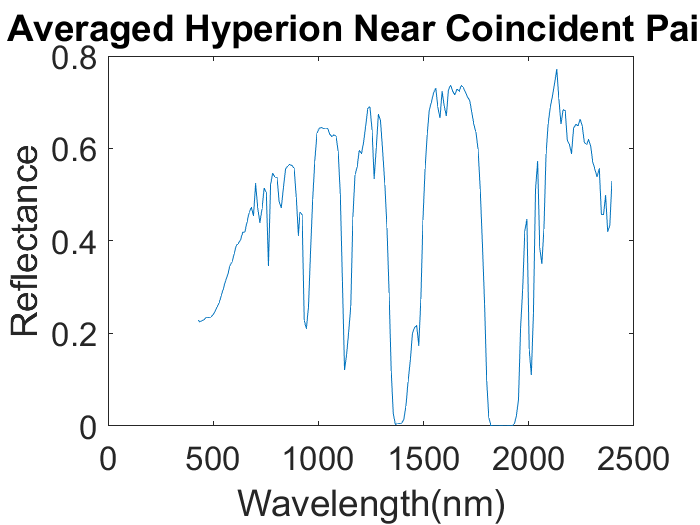

hyperionSpectrum = averageHyperionReflectanceCoincident;

%PLOTTING THE hYPERION sPECTRUM
figure
plot(hyperionWavelengths,hyperionSpectrum)
xlabel('Wavelength(nm)')
ylabel('Reflectance')
title('Averaged Hyperion Near Coincident Pairs')
ax = gca;
ax.FontSize = 20; 

## Model of Absolute calibration


$$\rho \text{\,}=\frac{\left(k-\text{scaleFactor}\ast \text{hyperion}\right)}{1-\left(s\text{za}-30\right)\ast \text{m1}-v\text{za}\ast \text{m2}-{v\text{za}}^2 \ast \text{m3}}$$


[data,dataTable,label,K] = modelDataCondition_2(satelliteNumber,hyperionSpectrum,gainFactor,hyperionWavelengths,sza,vza);

% multiplying the banded scale factor and banded hyperion reflectance
predictedNumerator = dataTable.Scale_Factor .* dataTable.Band_Refl

predictedNumerator =     0.2211
    0.2358
    0.3292
    0.4488
    0.5715
    0.6892
    0.6049
    0.3657
    0.0048


% mulitplying the angles with the coefficient
predictedDenominator = 1 - (sza_angle- 40)*transpose(dataTable.SZA) - vza_angle * transpose(dataTable.VZA_Lin) - sq_vza_angle*transpose(dataTable.VZA_Qua)

predictedDenominator =     1.0008    0.9999    0.9986    0.9975    0.9960    0.9939    0.9923    0.9982    0.9944
    1.0011    0.9986    0.9947    0.9912    0.9864    0.9800    0.9763    0.9934    0.9815
    1.0012    0.9986    0.9945    0.9910    0.9861    0.9795    0.9757    0.9933    0.9810
    1.0011    0.9986    0.9947    0.9912    0.9864    0.9800    0.9763    0.9934    0.9815
    1.0011    0.9987    0.9950    0.9917    0.9871    0.9811    0.9775    0.9938    0.9824
    1.0011    0.9988    0.9953    0.9923    0.9880    0.9824    0.9790    0.9942    0.9837
    1.0010    0.9990    0.9958    0.9931    0.9892    0.9841    0.9810    0.9948    0.9853
    1.0010    0.9992    0.9966    0.9942    0.9910    0.9867    0.9839    0.9957    0.9877
    1.0005    1.0010    1.0019    1.0027    1.0039    1.0054    1.0055    1.0022    1.0051
    1.0004    1.0013    1.0029    1.0043    1.0062    1.0088    1.0094    1.0034    1.0083


% repeating the predicted numerator
repeatedPredictedNumerator =  repmat(transpose(predictedNumerator),size(predictedDenominator,1),1)

repeatedPredictedNumerator =     0.2211    0.2358    0.3292    0.4488    0.5715    0.6892    0.6049    0.3657    0.0048
    0.2211    0.2358    0.3292    0.4488    0.5715    0.6892    0.6049    0.3657    0.0048
    0.2211    0.2358    0.3292    0.4488    0.5715    0.6892    0.6049    0.3657    0.0048
    0.2211    0.2358    0.3292    0.4488    0.5715    0.6892    0.6049    0.3657    0.0048
    0.2211    0.2358    0.3292    0.4488    0.5715    0.6892    0.6049    0.3657    0.0048
    0.2211    0.2358    0.3292    0.4488    0.5715    0.6892    0.6049    0.3657    0.0048
    0.2211    0.2358    0.3292    0.4488    0.5715    0.6892    0.6049    0.3657    0.0048
    0.2211    0.2358    0.3292    0.4488    0.5715    0.6892    0.6049    0.3657    0.0048
    0.2211    0.2358    0.3292    0.4488    0.5715    0.6892    0.6049    0.3657    0.0048
    0.2211    0.2358    0.3292    0.4488    0.5715    0.6892    0.6049    0.3657    0.0048



% predicted Reflectance 
predictedReflectance = repeatedPredictedNumerator./ predictedDenominator

predictedReflectance =     0.2210    0.2358    0.3296    0.4500    0.5738    0.6934    0.6096    0.3663    0.0048
    0.2209    0.2361    0.3309    0.4528    0.5794    0.7032    0.6196    0.3681    0.0049
    0.2209    0.2361    0.3310    0.4529    0.5796    0.7036    0.6200    0.3682    0.0049
    0.2209    0.2361    0.3309    0.4528    0.5794    0.7032    0.6195    0.3681    0.0049
    0.2209    0.2361    0.3308    0.4526    0.5790    0.7025    0.6188    0.3680    0.0049
    0.2209    0.2361    0.3307    0.4523    0.5784    0.7015    0.6178    0.3678    0.0048
    0.2209    0.2360    0.3305    0.4520    0.5777    0.7003    0.6166    0.3676    0.0048
    0.2209    0.2360    0.3303    0.4514    0.5767    0.6985    0.6147    0.3672    0.0048
    0.2210    0.2356    0.3285    0.4476    0.5693    0.6855    0.6016    0.3649    0.0047
    0.2210    0.2355    0.3282    0.4469    0.5680    0.6832    0.5992    0.3644    0.0047


label

label = 'Coastal Blue    Green   Red     NIR    SWIR1    SWIR2    Pan     Cirrus '

## Removing the Pan band from the list

predictedReflectance = predictedReflectance(:,1:7)

predictedReflectance =     0.2210    0.2358    0.3296    0.4500    0.5738    0.6934    0.6096
    0.2209    0.2361    0.3309    0.4528    0.5794    0.7032    0.6196
    0.2209    0.2361    0.3310    0.4529    0.5796    0.7036    0.6200
    0.2209    0.2361    0.3309    0.4528    0.5794    0.7032    0.6195
    0.2209    0.2361    0.3308    0.4526    0.5790    0.7025    0.6188
    0.2209    0.2361    0.3307    0.4523    0.5784    0.7015    0.6178
    0.2209    0.2360    0.3305    0.4520    0.5777    0.7003    0.6166
    0.2209    0.2360    0.3303    0.4514    0.5767    0.6985    0.6147
    0.2210    0.2356    0.3285    0.4476    0.5693    0.6855    0.6016
    0.2210    0.2355    0.3282    0.4469    0.5680    0.6832    0.5992


reflectance

reflectance =     0.2151    0.2292    0.3231    0.4538    0.5746    0.6890    0.6178
    0.2173    0.2305    0.3215    0.4485    0.5761    0.6972    0.5954
    0.2230    0.2369    0.3264    0.4535    0.5839    0.7063    0.6063
    0.2146    0.2278    0.3197    0.4515    0.5784    0.7037    0.6167
    0.2176    0.2304    0.3222    0.4516    0.5779    0.7001    0.6026
    0.2190    0.2317    0.3227    0.4518    0.5775    0.6978    0.6022
    0.2170    0.2293    0.3188    0.4450    0.5715    0.6928    0.5899
    0.2151    0.2273    0.3177    0.4453    0.5711    0.6929    0.5939
    0.2163    0.2275    0.3159    0.4401    0.5607    0.6757    0.5874
    0.2183    0.2311    0.3223    0.4481    0.5674    0.6687    0.5877


%percentage Difference between the two L8 reflectance
differenceInRef = predictedReflectance - reflectance

differenceInRef =     0.0059    0.0066    0.0065   -0.0038   -0.0008    0.0044   -0.0082
    0.0036    0.0056    0.0094    0.0044    0.0033    0.0060    0.0242
   -0.0021   -0.0008    0.0046   -0.0005   -0.0043   -0.0027    0.0136
    0.0063    0.0083    0.0113    0.0013    0.0010   -0.0005    0.0028
    0.0033    0.0057    0.0087    0.0010    0.0010    0.0024    0.0162
    0.0019    0.0044    0.0080    0.0006    0.0009    0.0038    0.0156
    0.0039    0.0067    0.0118    0.0069    0.0063    0.0075    0.0266
    0.0058    0.0087    0.0126    0.0061    0.0056    0.0056    0.0209
    0.0047    0.0081    0.0126    0.0075    0.0086    0.0098    0.0142
    0.0027    0.0044    0.0059   -0.0011    0.0006    0.0145    0.0115



percentageDiff = (differenceInRef ./ predictedReflectance)*100

percentageDiff =     2.6667    2.8185    1.9670   -0.8444   -0.1424    0.6297   -1.3402
    1.6093    2.3820    2.8552    0.9625    0.5726    0.8527    3.8990
   -0.9585   -0.3309    1.3954   -0.1194   -0.7373   -0.3782    2.1990
    2.8545    3.5228    3.4009    0.2843    0.1720   -0.0712    0.4599
    1.5016    2.4028    2.6195    0.2161    0.1782    0.3452    2.6159
    0.8755    1.8610    2.4240    0.1229    0.1639    0.5372    2.5308
    1.7612    2.8407    3.5649    1.5354    1.0823    1.0712    4.3197
    2.6328    3.6947    3.8238    1.3510    0.9656    0.8028    3.3925
    2.1377    3.4412    3.8491    1.6802    1.5082    1.4359    2.3536
    1.2351    1.8517    1.7949   -0.2547    0.1019    2.1207    1.9171


meanPercentDiff = nanmean(percentageDiff)

meanPercentDiff =     1.2087    2.1366    2.5138    0.1919    0.1498    0.6827    1.7854


## Root Mean Square Error

 % Root mean square calculation
squaredError = (differenceInRef).^2;
meanSquaredError = mean(squaredError);
% diferenceInRefmean = mean(differenceInRef)
RMSE =  sqrt(meanSquaredError) ./ egyptL8Mean

RMSE =     0.0176    0.0250    0.0278    0.0106    0.0088    0.0102    0.0248


RMSE_percentage = RMSE *100

RMSE_percentage =     1.7614    2.5023    2.7816    1.0620    0.8800    1.0238    2.4813


## Standard Deviation of the Residuals

stdResiduals = std(differenceInRef);
percentage = (stdResiduals./ egyptL8Mean) *100

percentage =     1.2754    1.2299    1.0496    1.0513    0.8728    0.7701    1.6986


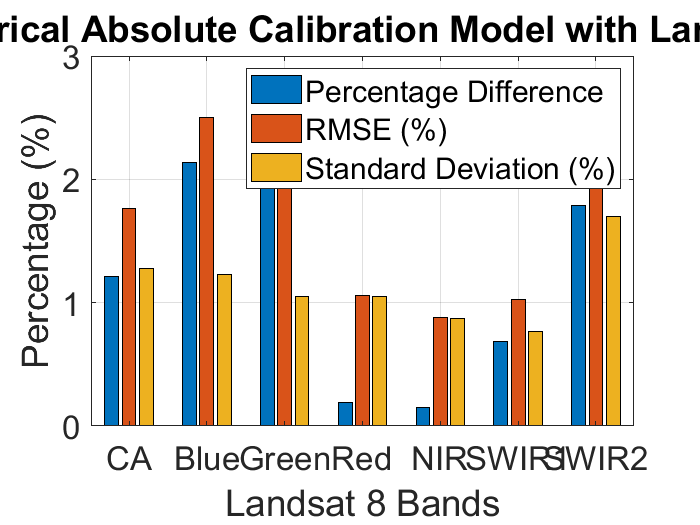


% bar plot
barplotValue = [meanPercentDiff;RMSE_percentage;percentage];
b = transpose(barplotValue);
bar(b)
xlabel('Landsat 8 Bands')
ylabel('Percentage (%)')
xticklabels({'CA','Blue','Green','Red','NIR','SWIR1','SWIR2'})
legend('Percentage Difference','RMSE (%)','Standard Deviation (%)')
grid on
ax= gca;
ax.FontSize  =  20;
title('Empirical Absolute Calibration Model with Landsat 8')

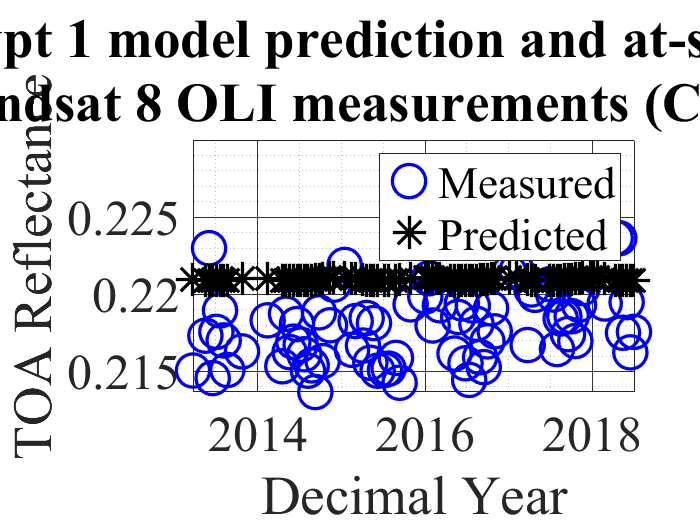

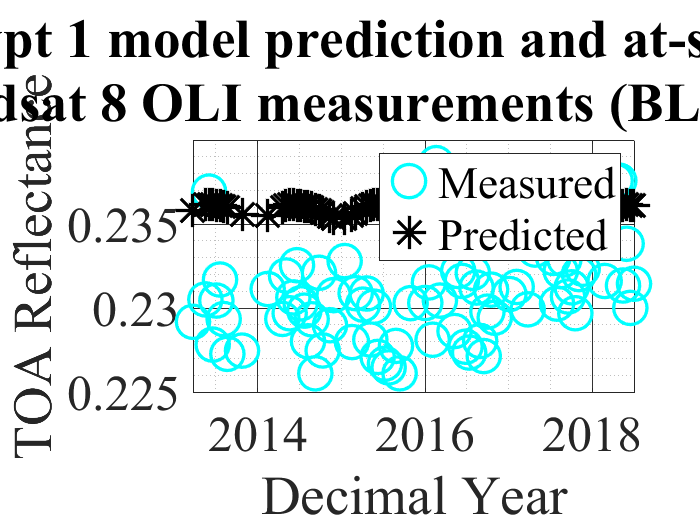

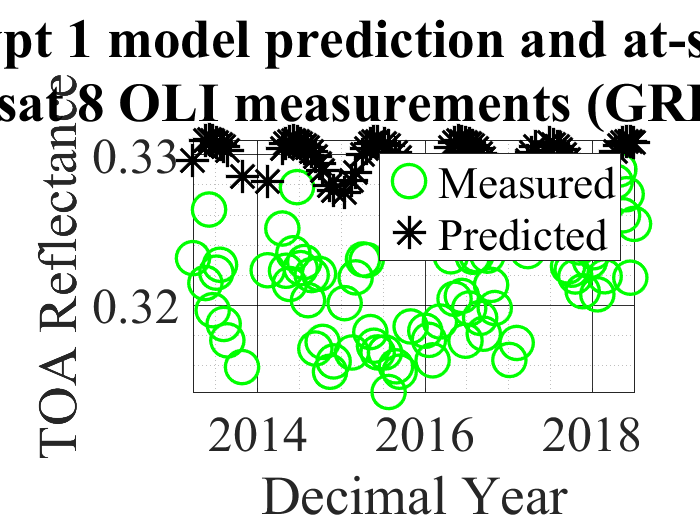

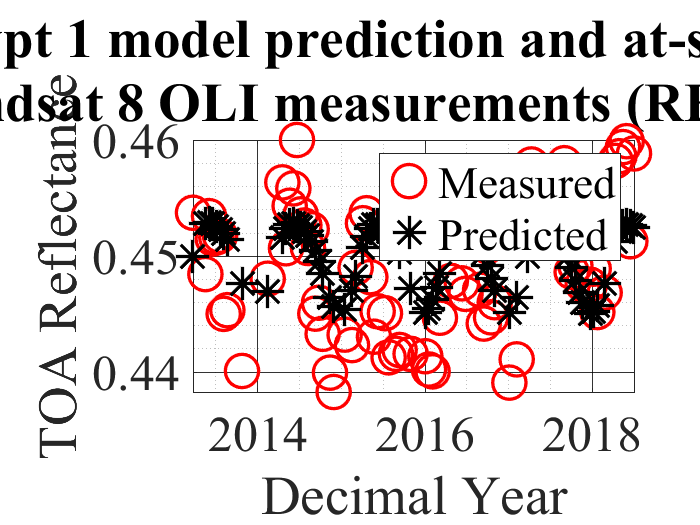

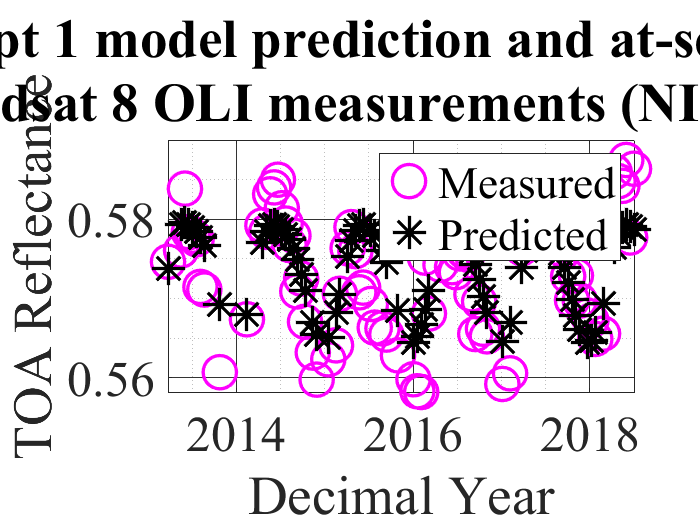

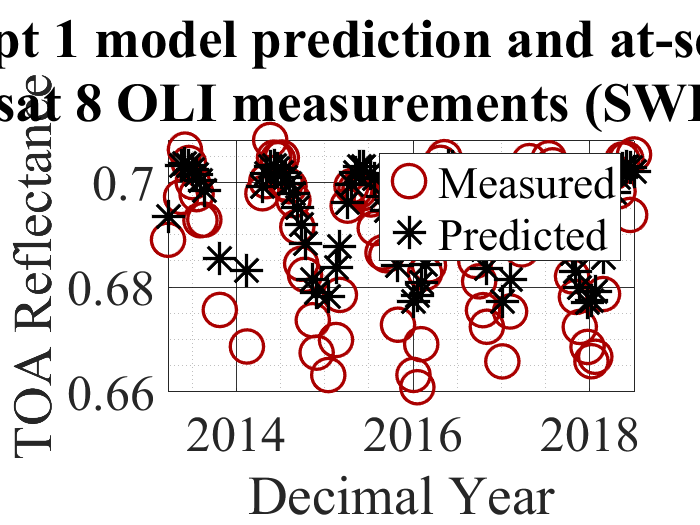

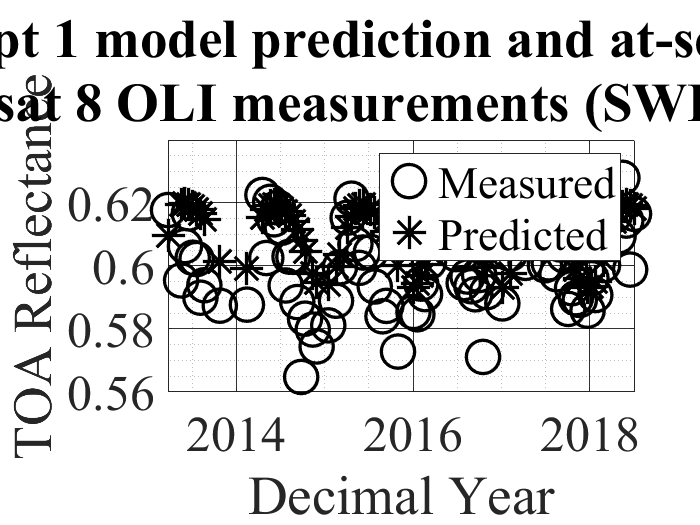

%% 

BandName = {'CA','BLUE', 'GREEN','RED', 'NIR' ,'SWIR1', 'SWIR2',};
bandColors={'b','c','g','r','m','[0.6667 0 0]','k'};

for band  = 1:7
    figure
    h= plot(decimalYear,reflectance(:,band),'LineStyle','None','Marker','o','Color',bandColors{band},'markers',20);
    set(h,'LineWidth',2);
    hold on
    h= plot(decimalYear,predictedReflectance(:,band),'LineStyle','None','Marker','*','Color','k','markers',20);
    set(h,'LineWidth',2);
    hold on
    
    xlabel('Decimal Year','Fontweight','bold')
    ylabel('TOA Reflectance','Fontweight','bold')
    title({['Comparison between Egypt 1 model prediction and at-sensor reflectance derived from'],['Landsat 8 OLI measurements (', BandName{band},' Band)']});
    legend('Measured','Predicted')
    grid on
    grid minor
    ax  = gca;
    ax.FontSize = 30;
    ax.GridColor = 'k';
    ax.GridAlpha = 0.8;
    ax.MinorGridColor = 'k';
    ax.FontName = 'Times New Roman';
end 

## Rsiduals plot

str = 1×1 cell array
    {'RMSE  = 0.88%\nSTD  = 0.87%'}


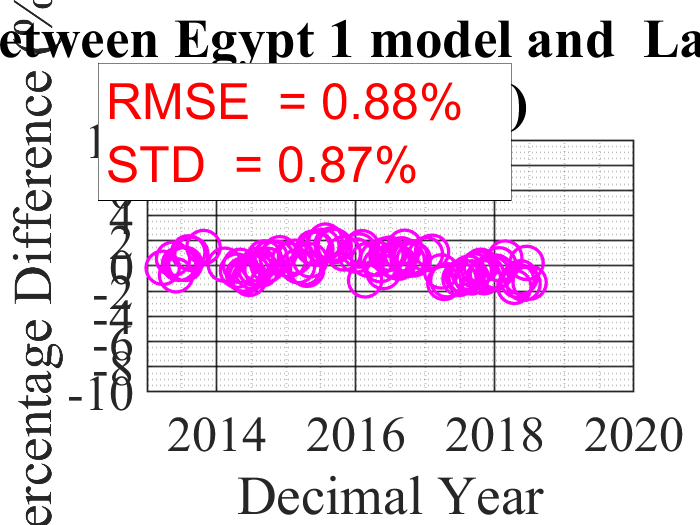


for band  = 5%1:7
    figure
    h = plot(decimalYear,percentageDiff(:,band),'LineStyle','None','Marker','o','Color',bandColors{band},'markers',20);
    set(h,'LineWidth',2);
    refline([0,0])
    title({['Percentage Difference between Egypt 1 model and  Landsat 8 OLI measurements'],['(',BandName{band},' Band)']})
    xlabel('Decimal Year','Fontweight','bold')
    ylabel('Percentage Difference (%)','FontWeight','bold')
    str = strcat('RMSE  = ', {' '},num2str(round(RMSE_percentage(band),2)),'%','\n', 'STD  = ',{' '},num2str(round(percentage(band),2)),'%')
    dim = [0.14 0.58 0.3 0.3];
    annotation('textbox',dim,'String',compose(str),'FitBoxToText','on','FontSize',30,'Color','red','Background','w');
    ax = gca;
    ax.FontSize = 22;
    textInfo  = strcat('Mean = ',meanPercentDiff(band),'\n','Std');
    text(2,8,'BLUE','Color','b','FontSize',14)
    grid on
    grid minor 
    ylim([-10,10])
    yticks([-10:2:10])
    ax = gca;
    ax.LineWidth = 1;
    ax.FontSize = 30;
    ax.GridColor = 'k';
    ax.GridAlpha = 0.8;
    ax.MinorGridColor = 'k';
     ax.FontName = 'Times New Roman';
end